## Zadanie 1

clear
clc

G = tf([1 1], [0.01, 0.5, 3 -10 10]) % obiekt

G =
 
                  s + 1
  --------------------------------------
  0.01 s^4 + 0.5 s^3 + 3 s^2 - 10 s + 10
 
Continuous-time transfer function.
Model Properties



% GR = K - regulator

Go = G % układ otwarty (K = 1)

Go =
 
                  s + 1
  --------------------------------------
  0.01 s^4 + 0.5 s^3 + 3 s^2 - 10 s + 10
 
Continuous-time transfer function.
Model Properties


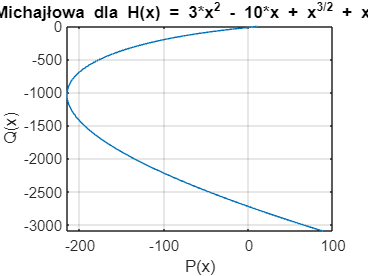

$$lim\_Re = \infty$$

$$lim\_Im = -\infty$$


[licz, mian] = tfdata(Go); % współczynniki wielomianów w liczniku i mianowniku transmitanjci układu otwartego
mian = mian{1};

Michajlow(mian, 18) % kryterium Michajłowa dla równania charakterystycznego układu otwartego

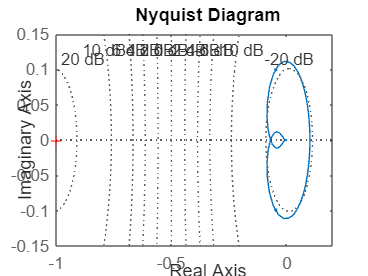


figure();
nyquist(Go); % wykres Nyquista
grid on;


% wyznaczenie wartości współczynnika K

syms w
Im_Go = (0.01*w^5-2.5*w^3+20*w)/((0.01*w^4-3*w^2+10)^2+(0.5*w^3+10*w)^2) % część urojona transmitancji widmowej uk. otwartego

$$Im\_Go = \frac{\frac{w^{5}}{100}-\frac{5\,w^{3}}{2}+20\,w}{{\left(\frac{w^{4}}{100}-3\,w^{2}+10\right)}^{2}+{\left(\frac{w^{3}}{2}+10\,w\right)}^{2}}$$

Re_Go = (-0.49*w^4-13*w^2+10)/((0.01*w^4-3*w^2+10)^2+(0.5*w^3+10*w)^2) % część rzeczywista transmitancji widmowej uk. otwartego

$$Re\_Go = -\frac{\frac{49\,w^{4}}{100}+13\,w^{2}-10}{{\left(\frac{w^{4}}{100}-3\,w^{2}+10\right)}^{2}+{\left(\frac{w^{3}}{2}+10\,w\right)}^{2}}$$


Im_0 = solve(Im_Go == 0, w)

$$Im\_0 = \left(\begin{array}{c} 0\\ -\sqrt{125-5\,\sqrt{5}\,\sqrt{109}}\\ -\sqrt{5\,\sqrt{5}\,\sqrt{109}+125}\\ \sqrt{125-5\,\sqrt{5}\,\sqrt{109}}\\ \sqrt{5\,\sqrt{5}\,\sqrt{109}+125} \end{array}\right)$$

Re_Go_function = matlabFunction(Re_Go);
Re_1 = Re_Go_function(0)

Re_1 = 0.1000

Re_2 = Re_Go_function(sqrt(125-5*sqrt(5)*sqrt(109))) % -1/K graniczne

Re_2 = -0.0707

Re_3 = Re_Go_function(sqrt(5*sqrt(5)*sqrt(109)+125)) % -1/K graniczne

Re_3 = -0.0076


K1 = -1/Re_2 % K graniczne

K1 = 14.1369

K2 = -1/Re_3 % K graniczne

K2 = 130.8631


% charakterystyki Bodego i Nicholsa uk. zamkniętego

K = 45; % przykładowe wzmocnienie regulatora

Go = K*G

Go =
 
                45 s + 45
  --------------------------------------
  0.01 s^4 + 0.5 s^3 + 3 s^2 - 10 s + 10
 
Continuous-time transfer function.
Model Properties



[Gm, Pm, Wcg, Wcp] = margin(Go) % zapasy stabilności

Gm = 2.9081

Pm = 15.6875

Wcg = 15.5475

Wcp = 7.9735

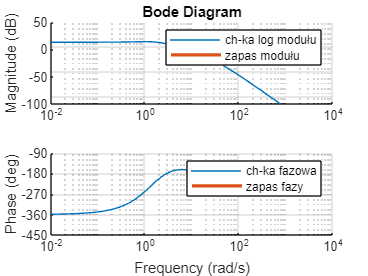

% Gm - zapas modułu
% Pm - zapas fazy
% Wcg - częstotliwości, dla których faza wynosi -pi
% Wcp - częstotliwości, dla których moduł wynosi 1

% wykresy Bodego
[mag, phase, wout] = bode(Go);
figure();
subplot(211);
hold on;
plot(wout, reshape(20*log10(mag), [78, 1])); % charakterystyka log modułu
plot(Wcg*ones(1, 100), linspace(-20*log10(Gm), 0, 100), "LineWidth", 2); % zapas modułu
hold off;
title("Bode Diagram");
ylabel("Magnitude (dB)");
set(gca, 'XScale', 'log');
ylim([-100, 50]);
yticks(-100:50:50);
grid on;
legend("ch-ka log modułu", "zapas modułu");
subplot(212);
hold on;
plot(wout, reshape(phase, [78, 1])); % charakterystyka fazowa
plot(Wcp*ones(1, 100), linspace(-180, -180+Pm, 100), "LineWidth", 2); % zapas fazy
hold off;
ylabel("Phase (deg)");
xlabel("Frequency (rad/s)")
set(gca, 'XScale', 'log');
ylim([-450, -90]);
yticks(-450:90:-90);
grid on;
legend("ch-ka fazowa", "zapas fazy");

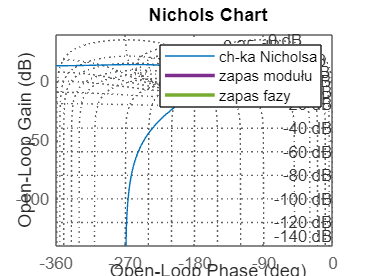


figure();
hold on;
nichols(Go); % wykres Nicholsa
plot(-180*ones(1, 100), linspace(0, -20*log10(Gm), 100), "LineWidth", 2); % zapas modułu
plot(linspace(-180, -180+Pm), zeros(1, 100), "LineWidth", 2); % zapas fazy
hold off;
grid on;
legend("ch-ka Nicholsa", "zapas modułu", "zapas fazy");

## Zadanie 2

clear
clc

G = tf([4], [1, 1], "OutputDelay", 0.5) % obiekt

G =
 
                  4
  exp(-0.5*s) * -----
                s + 1
 
Continuous-time transfer function.
Model Properties


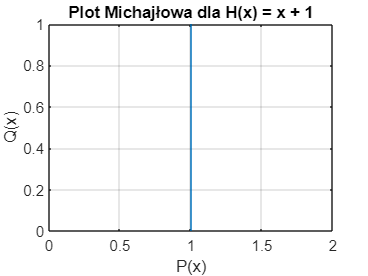

$$lim\_Re = 1$$

$$lim\_Im = \infty$$


[licz, mian] = tfdata(G); % współczynniki wielomianów w liczniku i mianowniku transmitanjci obiektu
mian = mian{1};

Michajlow(mian, 1) % kryterium Michajłowa dla równania charakterystycznego obiektu

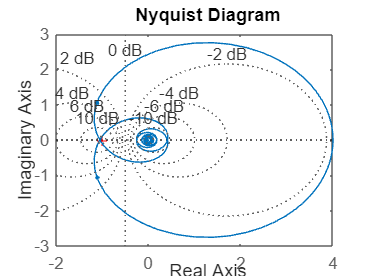


figure();
nyquist(G); % wykres Nyquista
grid on;


K = -1/-1.03904 % K graniczne - odczytane z wykresu

K = 0.9624


% sprawdzanie stabilności uk. zamkniętego w zależności od opóźnienia tau
syms w tau;
w_1 = solve(4/sqrt(1+w^2)-1==0, w) % omega, dla którego wartość modułu wynosi 1

$$w\_1 = \left(\begin{array}{c} \sqrt{15}\\ -\sqrt{15} \end{array}\right)$$

tau_graniczne_1 = solve(pi+atan(-sqrt(15))+tau*(-sqrt(15))==0, tau) % granica stabilności układu ze względu na tau - 1

$$tau\_graniczne\_1 = \frac{8212208454930187\,\sqrt{15}}{67553994410557440}$$

tau_graniczne_2 = solve(pi+atan(sqrt(15))+tau*(sqrt(15))==0, tau) % granica stabilności układu ze względu na tau - 2

$$tau\_graniczne\_2 = -\frac{1673728546098631\,\sqrt{15}}{5629499534213120}$$

## Funckje

function [] = Michajlow(M, n_w)
    % M - wsp. wielomianu charakterystycznego uk. otwartego
    if M(1) > 0 && M(end) ~= 0 % warunki: a_n > 0, 0 nie jest rozwiązaniem równania
        H_s = poly2sym(M); % równanie charakterytyczne
        H_s_f = matlabFunction(H_s);
        Re_H = @(w) real(H_s_f(1i*w)); % część rzeczywista wielomianu H(s)
        Im_H = @(w) imag(H_s_f(1i*w)); % część urojona wielomianu H(s)
        w = linspace(0, n_w, 1000); % wektor częstotliwości
        figure(); % wykres Michajłowa
        plot(Re_H(w), Im_H(w));
        title(append("Plot Michajłowa dla H(x) = ", string(H_s)))
        xlabel("P(x)");
        ylabel("Q(x)");
        grid on;
        syms w; % granice w nieskończoności P(w), Q(w)
        Re_H_sym = Re_H(w);
        Im_H_sym = Im_H(w);
        lim_Re = limit(Re_H_sym, w, Inf)
        lim_Im = limit(Im_H_sym, w, Inf)
    end
end